# Practica Final

## Datos del alumno

Nombre: **Bejarano Lozada Elias**

Numero de control:** 20213057**

Correo institucional: elias.bejarano201**@tectijuan.edu.mx**

Asignatura: **Modelado de Sistemas Fisiologicos**

Carrera: **Ingenieria Biomedica**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Datos generales de la simulacion**

clc; clear all; close all;
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';


## Respuesta

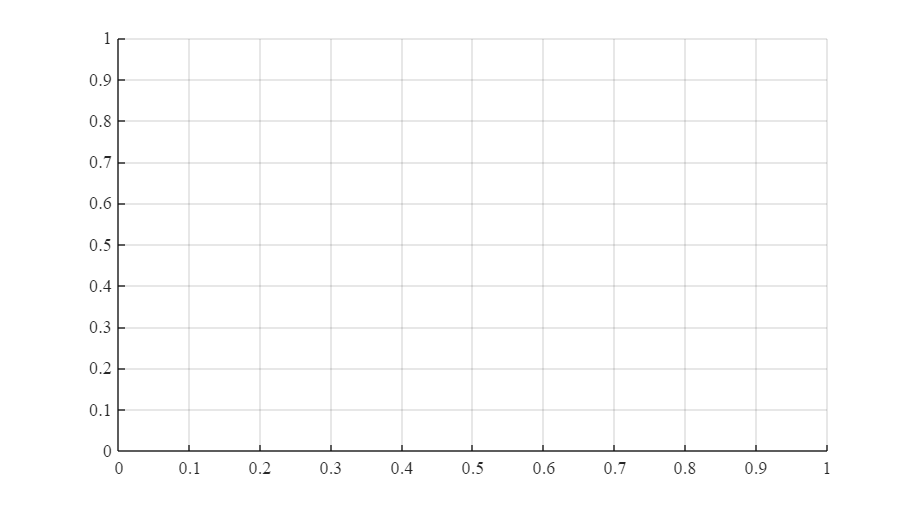

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

Error in SIRA>plotSignal (line 16)
plot(tout, Zax , 'LineWidth', 2 ,'Color',[0.95,0.65,0.15]);

S= sim(file,parameters);
plotSignal(S.tout,S.Zax,S.Zay,S.Zaz,S.Zab)

## Funcion: Respuesta de las señales

function plotSignal(tout,Zax,Zay,Zaz,Zab)
set(figure(), 'color', 'w')
set(gcf, 'units', 'centimeters', 'position',[1,5,18,10])
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
hold on; grid on

plot(tout, Zax , 'LineWidth', 2 ,'Color',[0.95,0.65,0.15]);
plot(tout, Zay, 'LineWidth',2, 'Color',[0,0.25,0.4]);
plot(tout, Zaz, ':','LineWidth', 2 ,'Color',[0.3,0.5,0.2]);
plot(tout, Zab, 'LineWidth',2, 'Color',[0.5,0.05,0.05]);

L = legend('$Zao(t)$','$ZA(t): Tratamiento$','$ZA(t): Control$','$ZA(t): Caso$');
set(L,'Interpreter','Latex', 'FontSize', 9, 'Location','NorthEastOutside')
title(L,'Signals')

xlabel('$tiempo$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$V(t)$ $[P.$ $tejido$ $pulmonar]$','Interpreter','Latex','FontSize',9)
 
xlim([0,10]); xticks (0:1:10)
ylim([-2,2]); yticks(-2:0.2:2)
name = 'ProyectoFinalModelado.pdf';
exportgraphics(gcf,name,'ContentType','vector')
end